# System Identification (GPC)

## 0. Helpers

function [theta, yhat, ehat, info] = carima_els_mimo(y, u, na, nb, nc, d, maxIter, tol)
% Extended Least Squares for MIMO incremental CARIMA/ARMAX:
% y(k) = -A1 y(k-1)-...-Ana y(k-na) + B0 u(k-1-d)+...+Bnb u(k-1-d-nb)
%        + C1 e(k-1)+...+Cnc e(k-nc) + e(k)

    [N, ny] = size(y);
    nu = size(u,2);

    nAy = ny * na;
    nBu = nu * (nb + 1);
    nCe = ny * nc;
    nTheta = nAy + nBu + nCe;

    k0 = max([na, nb + d + 1, nc]) + 1;

    % --- ARX initialization (C = I, i.e., no MA terms) ---
    theta = zeros(nTheta, ny);
    theta_arx = arx_ls_mimo(y, u, na, nb, d);
    theta(1:nAy+nBu, :) = theta_arx;

    % Initial residuals from ARX predictor
    [yhat, ehat] = carima_osa_predict_mimo(y, u, theta, na, nb, nc, d);

    info.cost = nan(maxIter,1);
    info.relchg = nan(maxIter,1);

    for iter = 1:maxIter
        S = zeros(nTheta, nTheta);
        rhs = zeros(nTheta, ny);

        for k = k0:N
            phi_y = reshape(-y(k-1:-1:k-na, :).', [], 1);  % ny*na x 1
            phi_u = reshape( u(k-1-d:-1:k-1-d-nb, :).', [], 1); % nu*(nb+1) x 1
            if nc > 0
                phi_e = reshape(ehat(k-1:-1:k-nc, :).', [], 1); % ny*nc x 1
                phi = [phi_y; phi_u; phi_e];
            else
                phi = [phi_y; phi_u];
            end

            S = S + phi * phi.';
            rhs = rhs + phi * y(k,:);
        end

        % small regularization for numerical robustness
        theta_new = (S + 1e-6 * eye(nTheta)) \ rhs;

        [yhat_new, ehat_new] = carima_osa_predict_mimo(y, u, theta_new, na, nb, nc, d);

        idx = k0:N;
        cost = norm(ehat_new(idx,:), "fro")^2;
        relchg = norm(theta_new - theta, "fro") / max(1, norm(theta, "fro"));

        info.cost(iter) = cost;
        info.relchg(iter) = relchg;

        theta = theta_new;
        yhat = yhat_new;
        ehat = ehat_new;

        if relchg < tol
            break;
        end
    end

    info.nIter = iter;
    info.cost = info.cost(1:iter);
    info.relchg = info.relchg(1:iter);
end


function theta_arx = arx_ls_mimo(y, u, na, nb, d)
% Least-squares ARX initializer (no noise polynomial terms)
    [N, ny] = size(y);
    nu = size(u,2);

    nAy = ny * na;
    nBu = nu * (nb + 1);
    nTheta = nAy + nBu;

    k0 = max([na, nb + d + 1]) + 1;

    S = zeros(nTheta, nTheta);
    rhs = zeros(nTheta, ny);

    for k = k0:N
        phi_y = reshape(-y(k-1:-1:k-na, :).', [], 1);
        phi_u = reshape( u(k-1-d:-1:k-1-d-nb, :).', [], 1);
        phi = [phi_y; phi_u];

        S = S + phi * phi.';
        rhs = rhs + phi * y(k,:);
    end

    theta_arx = (S + 1e-10 * eye(nTheta)) \ rhs;
end


function [yhat, ehat, k0] = carima_osa_predict_mimo(y, u, theta, na, nb, nc, d)
% One-step-ahead predictor for MIMO ARMAX/CARIMA incremental model
% Uses recursively computed innovations ehat in the C(q^-1) term.

    [N, ny] = size(y);
    nu = size(u,2);

    nAy = ny * na;
    nBu = nu * (nb + 1);
    nCe = ny * nc;
    nTheta = nAy + nBu + nCe;

    if size(theta,1) ~= nTheta || size(theta,2) ~= ny
        error("theta size mismatch. Expected [%d x %d], got [%d x %d].", ...
            nTheta, ny, size(theta,1), size(theta,2));
    end

    yhat = nan(N, ny);
    ehat = zeros(N, ny);

    k0 = max([na, nb + d + 1, nc]) + 1;

    for k = k0:N
        phi_y = reshape(-y(k-1:-1:k-na, :).', [], 1);
        phi_u = reshape( u(k-1-d:-1:k-1-d-nb, :).', [], 1);

        if nc > 0
            phi_e = reshape(ehat(k-1:-1:k-nc, :).', [], 1);
            phi = [phi_y; phi_u; phi_e];
        else
            phi = [phi_y; phi_u];
        end

        yhat(k,:) = (phi.' * theta);   % 1 x ny
        ehat(k,:) = y(k,:) - yhat(k,:);
    end
end

## 1. Load + format data

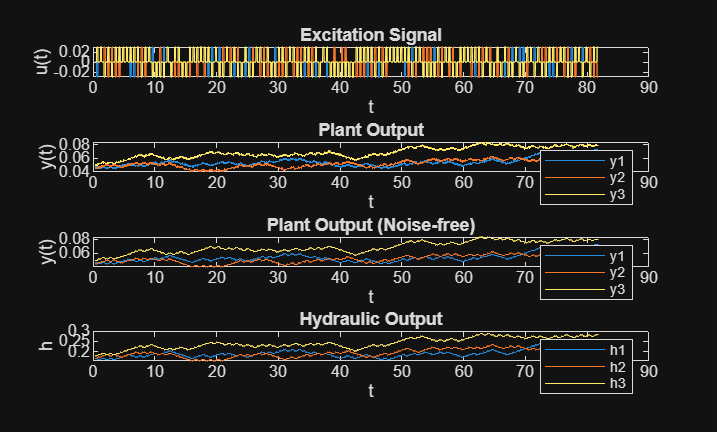

data_path = fullfile("data", "IdMPC_est.mat");
Ts = 0.02;
load(data_path);
% Drop the first sample
startIdx = 20;
t = t(startIdx:end, :);
u = u(startIdx:end, :);
y = y(startIdx:end, :);
y_real = y_real(startIdx:end, :);
l_hy = l_hy(startIdx:end, :);

figure;
subplot(4, 1, 1);
plot(t, u);
title('Excitation Signal'); xlabel('t'); ylabel('u(t)');
subplot(4, 1, 2);
plot(t, y);
title('Plant Output'); xlabel('t'); ylabel('y(t)');
legend("y1", "y2", "y3");
subplot(4, 1, 3);
plot(t, y_real);
title('Plant Output (Noise-free)'); xlabel('t'); ylabel('y(t)');
legend("y1", "y2", "y3");
subplot(4, 1, 4);
plot(t, l_hy);
title('Hydraulic Output'); xlabel('t'); ylabel('h');
legend("h1", "h2", "h3");

## 2. Create `iddata` + detrend

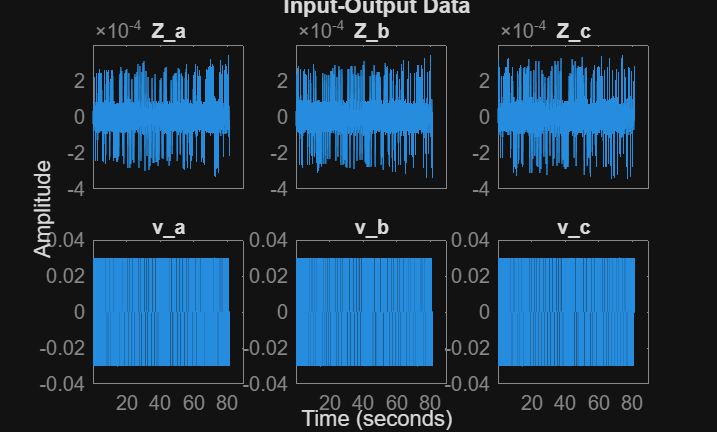

% y = diff(y);
y = diff(y_real);
u = diff(u);

data = iddata(y, u, Ts, "TimeUnit", "s");
data.InputName = {"v_a", "v_b", "v_c"};
data.OutputName = {"Z_a", "Z_b", "Z_c"};

% remove mean
% data = detrend(data, 0);

figure;
idplot(data);

## 3. Split estimation/validation

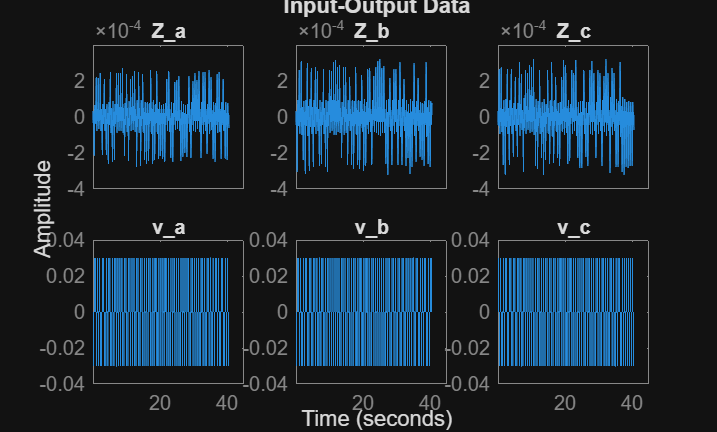

% N = size(data.OutputData, 1);
% Ne = floor(0.7*N);
% 
% data_est = data(1:Ne);
% data_val = data(Ne+1:end);

data_est = data;
data_path = fullfile("data", "IdMPC_val.mat");
load(data_path);
t = t(startIdx:end, :);
u = u(startIdx:end, :);
% y = y(startIdx:end, :);
y = y_real(startIdx:end, :);
l_hy = l_hy(startIdx:end, :);

u = diff(u);
y = diff(y);

data_val = iddata(y, u, Ts, "TimeUnit", "s");
data_val.InputName = {"v_a", "v_b", "v_c"};
data_val.OutputName = {"Z_a", "Z_b", "Z_c"};
figure;
idplot(data_val);

## 4. Estimate CARIMA model

y_est = data_est.y;   % these are already diff(y)
u_est = data_est.u;   % these are already diff(u)
y_val = data_val.y;
u_val = data_val.u;

n_a = 2:10;
n_b = 1:10;
n_c = 0:2;    % <-- noise polynomial order C(q^-1) = 1 + c1 q^-1 + ... + cnc q^-nc
d   = 0;      % input delay
maxELSIter = 20;
tolELS = 1e-4;

fit_best = -Inf;
theta_best = [];
na_best = 0; nb_best = 0; nc_best = 0;

for na = n_a
    for nb = n_b
        for nc = n_c
            try
                [theta_hat, yhat_est, ehat_est, info] = carima_els_mimo( ...
                    y_est, u_est, na, nb, nc, d, maxELSIter, tolELS);

                % One-step-ahead validation prediction (uses noise model recursively)
                [yhat_val, ~, k0] = carima_osa_predict_mimo( ...
                    y_val, u_val, theta_hat, na, nb, nc, d);

                idx = k0:size(y_val,1);
                fit = 100 * (1 - norm(y_val(idx,:) - yhat_val(idx,:)) / ...
                    norm(y_val(idx,:) - mean(y_val(idx,:),1)));

                fprintf("na=%d, nb=%d, nc=%d, fit=%.2f%%, ELS iters=%d\n", ...
                    na, nb, nc, fit, info.nIter);

                if fit > fit_best + 0.1
                    fit_best = fit;
                    theta_best = theta_hat;
                    na_best = na;
                    nb_best = nb;
                    nc_best = nc;
                    info_best = info;
                end
            catch ME
                fprintf("na=%d, nb=%d, nc=%d failed: %s\n", na, nb, nc, ME.message);
            end
        end
    end
end

na=2, nb=1, nc=0, fit=84.67%, ELS iters=2
na=2, nb=1, nc=1, fit=87.95%, ELS iters=8
na=2, nb=1, nc=2, fit=88.49%, ELS iters=11
na=2, nb=2, nc=0, fit=84.94%, ELS iters=2
na=2, nb=2, nc=1, fit=86.89%, ELS iters=10
na=2, nb=2, nc=2, fit=87.31%, ELS iters=11
na=2, nb=3, nc=0, fit=86.09%, ELS iters=2
na=2, nb=3, nc=1, fit=87.16%, ELS iters=8
na=2, nb=3, nc=2, fit=87.21%, ELS iters=10
na=2, nb=4, nc=0, fit=86.76%, ELS iters=2
na=2, nb=4, nc=1, fit=87.66%, ELS iters=9
na=2, nb=4, nc=2, fit=87.64%, ELS iters=8
na=2, nb=5, nc=0, fit=87.14%, ELS iters=2
na=2, nb=5, nc=1, fit=88.27%, ELS iters=8
na=2, nb=5, nc=2, fit=88.29%, ELS iters=9
na=2, nb=6, nc=0, fit=87.41%, ELS iters=2
na=2, nb=6, nc=1, fit=89.18%, ELS iters=10
na=2, nb=6, nc=2, fit=89.29%, ELS iters=9
na=2, nb=7, nc=0, fit=87.40%, ELS iters=2
na=2, nb=7, nc=1, fit=90.01%, ELS iters=11
na=2, nb=7, nc=2, fit=90.48%, ELS iters=9
na=2, nb=8, nc=0, fit=87.32%, ELS iters=2
na=2, nb=8, nc=1, fit=90.32%, ELS iters=9
na=2, nb=8, nc=2, fit=91.00%


fprintf("\nBest orders: na=%d, nb=%d, nc=%d, fit=%.2f%%\n", ...
    na_best, nb_best, nc_best, fit_best);


Best orders: na=8, nb=8, nc=1, fit=95.99%


## 5. Validate the model

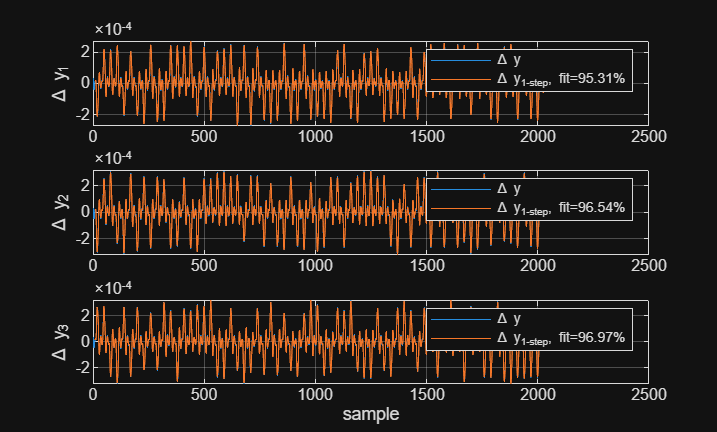

y = data_val.y;   % diff(y)
u = data_val.u;   % diff(u)

[y_hat, e_hat, k0] = carima_osa_predict_mimo(y, u, theta_best, na_best, nb_best, nc_best, d);

figure;
for i = 1:3
    fit_i = 100 * (1 - norm(y(k0:end,i) - y_hat(k0:end,i)) / ...
        norm(y(k0:end,i) - mean(y(k0:end,i))));
    subplot(3,1,i);
    plot(y(:,i)); hold on;
    plot(y_hat(:,i)); hold off;
    grid on;
    legend("\Delta y", sprintf("\\Delta y_{1-step}, fit=%.2f%%", fit_i));
    ylabel(sprintf("\\Delta y_%d",i));
end
xlabel("sample");

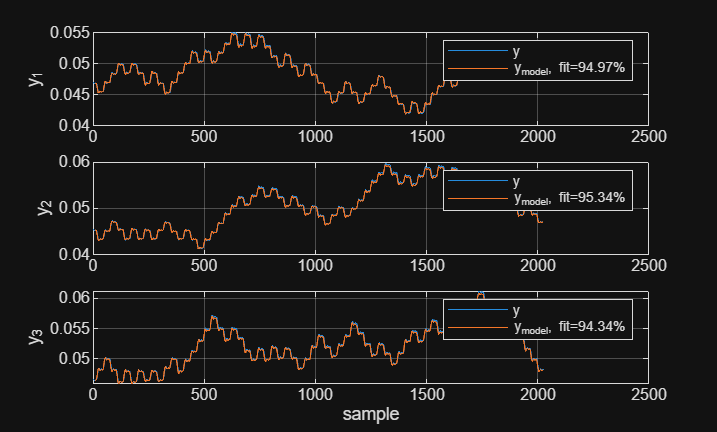


% reconstruct original y from predicted delta-y (one-step style)
load("data/IdMPC_val.mat", "y_real");
y_raw = y_real(startIdx:end, :);   % original (not differenced)
y_model = nan(size(y_raw));

% Reconstruct from k0 onward using cumulative sum of predicted delta-y
y_model(k0,:) = y_raw(k0,:);
for k = k0+1:size(y_hat,1)
    y_model(k,:) = y_model(k-1,:) + y_hat(k,:);
end

figure;
for i = 1:3
    idx = k0:size(y_hat,1);
    fit_i = 100 * (1 - norm(y_raw(idx,i) - y_model(idx,i)) / ...
        norm(y_raw(idx,i) - mean(y_raw(idx,i))));
    subplot(3,1,i);
    plot(y_raw(:,i)); hold on;
    plot(y_model(:,i)); hold off;
    grid on;
    legend("y", sprintf("y_{model}, fit=%.2f%%", fit_i));
    ylabel(sprintf("y_%d",i));
end
xlabel("sample");

## 6. GPC parameters

% theta rows are ordered in 3x3 blocks:
% [A1 ... Ana, B0 ... Bnb, C1 ... Cnc]
ThetaBlk = reshape(theta_best', 3, 3, []);

A = cat(3, eye(3), ThetaBlk(:,:,1:na_best));
B = ThetaBlk(:,:,na_best+1 : na_best+nb_best+1);

if nc_best > 0
    C = cat(3, eye(3), ThetaBlk(:,:,na_best+nb_best+2 : na_best+nb_best+1+nc_best));
else
    C = eye(3);   % C(q^-1) = I
end

% save("data/GPC_params.mat", "A", "B", "C", "na_best", "nb_best", "nc_best", "d", "Ts");